# 15 Short-Time FFT

The short-time FFT is a simple extension of the Fourier transform that provides time-frequency power and phase information while addressing its two main limitations in EEG time-frequency analysis:

- The Fourier transform obscures time-varying changes in the frequency structure of the data

- The Fourier transform assumes that the data are stationary for the duration of the time series

## 15.1 How the Short-Time FFT Works

The short-time FFT works like the Fourier transform, except that it extracts the frequency structure of short time windows rather than analyzing the entire time series at once:

- The data are segmented into short, overlapping time windows, which are selected sequentially across the entire time series.

- A windowing taper is applied to each segment to minimize edge artifacts.

- The Fourier transform is computed for the tapered segment.

- The power spectrum of the segment is calculated from the Fourier-transformed data.

- The resulting power spectrum is entered into a time-frequency matrix, where the frequency dimension corresponds to the FFT frequencies and the time dimension corresponds to the center time point of the analyzed segment.

- These steps are repeated for all time windows to construct the complete time-frequency representation of the signal 

It is not necessary to perform these procedures separately for each trial because the Matlab function fft can accept a 2-D input (e.g., time by trials). The FFT returns as many frequencies between DC and the Nyquist frequency as there are time points in the segment, although you can keep only the frequencies of interest. For resting-state data, the same procedure could be applied, but the FFT results would be averaged over time.

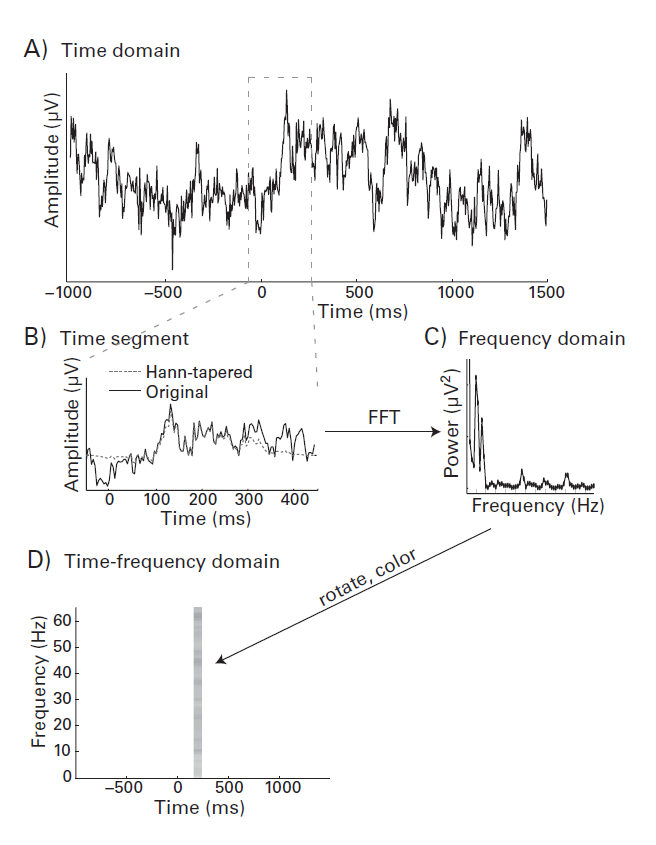

**Figure 15.1**

*Overview of the short-time FFT method. From the time series data, a small segment of the data, comprising a few hundred milliseconds, is taken.*

From two-dimensional (2-D) result (time by frequency), you can extract the time course of power at one frequency or the power spectrum at one time point.

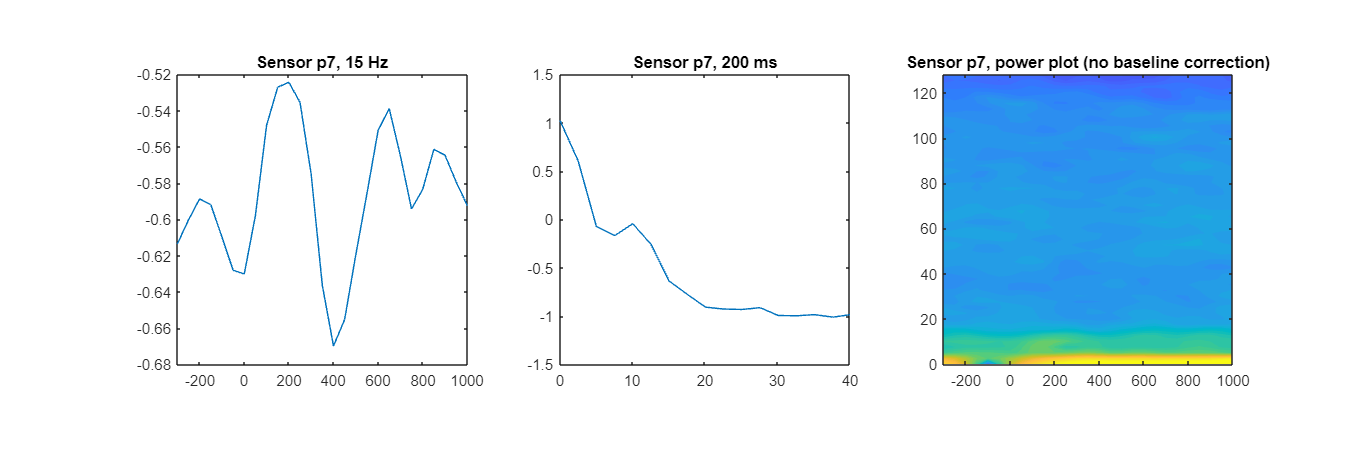

load sampleEEGdata

timewin        = 400;
times2save     = -300:50:1000;
channel2plot   = 'p7';
frequency2plot = 15;
timepoint2plot = 200;

times2saveidx = zeros(size(times2save));
for i=1:length(times2save)
    [~,times2saveidx(i)]=min(abs(EEG.times-times2save(i)));
end
timewinidx = round(timewin/(1000/EEG.srate));
chan2useidx = strcmpi(channel2plot,{EEG.chanlocs.labels});

hann_win = .5*(1-cos(2*pi*(0:timewinidx-1)/(timewinidx-1)));
frex = linspace(0,EEG.srate/2,floor(timewinidx/2)+1);
tf = zeros(length(frex),length(times2save));

for timepointi=1:length(times2save)
    
    tempdat = squeeze(EEG.data(chan2useidx,times2saveidx(timepointi)-floor(timewinidx/2):times2saveidx(timepointi)+floor(timewinidx/2)-mod(timewinidx+1,2),:));
    taperdat = bsxfun(@times,tempdat,hann_win');
    fdat = fft(taperdat,[],1)/timewinidx;
    tf(:,timepointi) = mean(abs(fdat(1:floor(timewinidx/2)+1,:)).^2,2);
end


figure(Position=[100,100,1500,500])

subplot(131)
[~,freq2plotidx]=min(abs(frex-frequency2plot));
plot(times2save,mean(log10(tf(freq2plotidx-2:freq2plotidx+2,:)),1))
title([ 'Sensor ' channel2plot ', ' num2str(frequency2plot) ' Hz' ])
axis square
set(gca,'xlim',[times2save(1) times2save(end)])

subplot(132)
[junk,time2plotidx]=min(abs(times2save-timepoint2plot));
plot(frex,log10(tf(:,time2plotidx)))
title([ 'Sensor ' channel2plot ', ' num2str(timepoint2plot) ' ms' ])
axis square
set(gca,'xlim',[frex(1) 40])

subplot(133)
contourf(times2save,frex,log10(tf),40,'linecolor','none')
set(gca,'clim',[-2 1])
title([ 'Sensor ' channel2plot ', power plot (no baseline correction)' ])
axis square
hold on

**Figure 15.2**

*Power over time and power structure at one time segment obtained from the short time FFT method. No baseline transformation was applied in these plots.*

## 15.2 Taper the Time Series

Before computing the Fourier transform of each time segment, you should taper the data in that segment. This will attenuate the amplitude of the data at the beginning and at the end of the time segment, which is important for preventing edge artifacts from contaminating the time-frequency results. Note that this means that large buffer zones at the start and end of each trial are not necessary for the short-time FFT method. The downside of tapering is that it attenuates valid EEG signal, but this effect can be mitigated by using temporally overlapping segments.

There are several possible tapers to use, including: 

- Hann: tapers the data fully to zero at the beginning and end of the time segment

- Hamming: does not fully taper the data to zero

- Gaussian: tapers the data fully to zero but the window becomes fairly narrow, which may excessively taper the data

- Kaiser

- Cosine

- Blackman

The two features to look for In a taper are: 

- Width 

- Beginning and at the end of the window

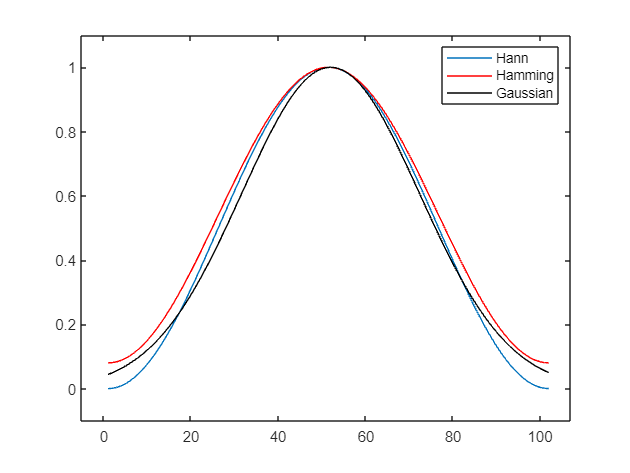

hamming_win = .54 - .46*cos(2*pi*(0:timewinidx-1)/(timewinidx-1));
hann_win    = .5*(1-cos(2*pi*(0:timewinidx-1)/(timewinidx-1)));
gaus_win = exp(-.5*(2.5*(-timewinidx/2:timewinidx/2-1)/(timewinidx/2)).^2);

figure
plot(hann_win)
hold on
plot(hamming_win,'r')
plot(gaus_win,'k')
legend({'Hann';'Hamming';'Gaussian'})

set(gca,'xlim',[-5 timewinidx+5],'ylim',[-.1 1.1],'ytick',0:.2:1)

**Figure 15.3**

*Different tapering functions often used for the short-time FFT in EEG data.*

Because the number of frequencies returned by the FFT is equal to N /2 + 1 there will probably be more frequencies than you want to include in the analyses. Thus, you can select only those frequencies that you want to analyze. Sampling the requested frequencies is necessary if the length of the time segment changes as a function of frequency because the indices corresponding to each frequency will vary with the length of the time segment.

To obtain the requested frequencies you can:

- Select the single frequency bin closest to each requested frequency 

- Average neighboringfrequencies

- Apply a distance weighting such as a Gaussian to neighboring frequencies to compute a weighted average

The latter two options increase the signal-to-noise ratio of the results of the short-time FFT.

Note that taking the average power from several neighboring frequencies makes the result of the short-time FFT method more similar to results from the filter-Hilbert method. To make the results from the short-time FFT method more similar to the results of complex wavelet convolution, you could average Gaussian-weighted neighboring frequencies.

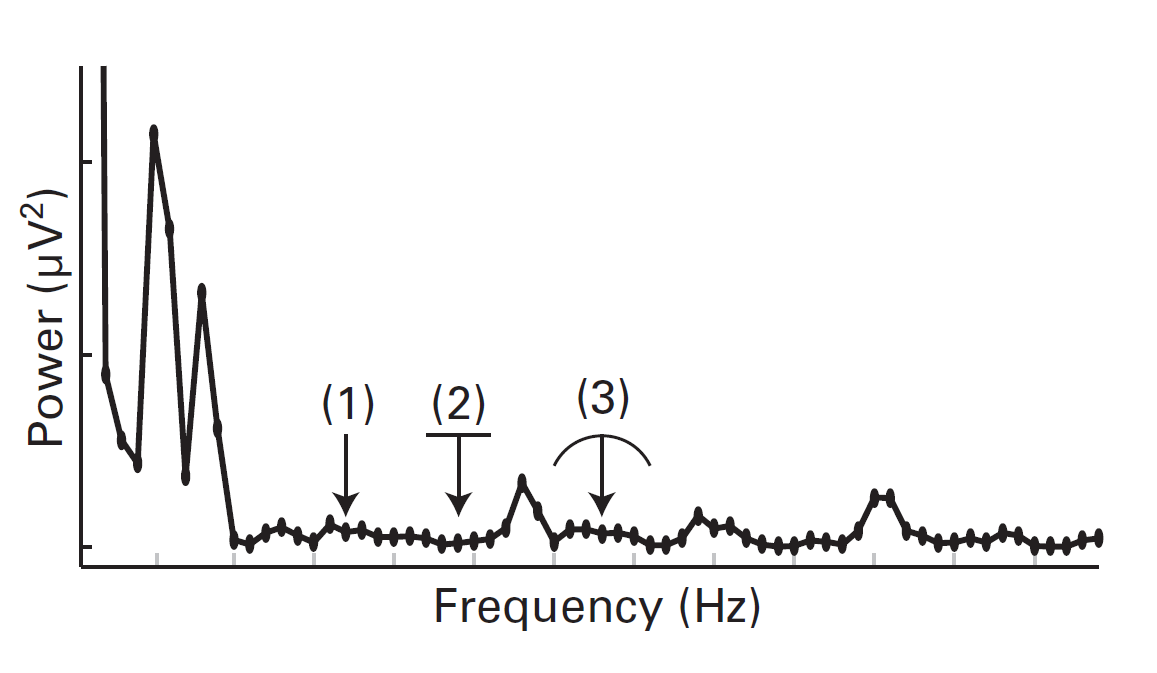

**Figure 15.4**

*Illustration of different ways of extracting frequencies from the FFT of each time segment.*

It was mentioned earlier that buffer zones are not necessary for the short-time FFT method. However, you still need to create longer epochs than you would for ERP-only analyses because of the time segment lengths.

## 15.3 Time Segment Lengths and Overlap

The length of the time segment offers the much-discussed trade-off between temporal and frequency precision and resolution: 

- Shorter time segments provide better temporal precision at the expense of frequency precision and resolution

- Longer time segments provide better frequency precision and resolution at the expense of temporal precision 

The choice of time segment length is also related to the lowest frequency you want to analyze. The segment must be long enough to capture at least one cycle of the lowest frequency, and preferably more than one cycle to increase signal-to-noise ratio.

To adapt the short-time FFT method such that the trade-off between temporal precision and frequency precision changes as a function of frequency, you can change the time segment length as a function of frequency: 

- Lower frequencies can have longer time segments

- Higher frequencies can have shorter time segments

This procedure will have a similar effect to wavelet convolution with a variable number of cycles as a function of frequency. In this case the FFT will be performed several times on time segments around each time point. Each time the FFT is performed, a range of frequenciesis extracted.

A second parameter of the short-time FFT is the amount of overlap between successive time segments. Having temporal overlap is useful for three reasons: 

- It improves the temporal precision

- It mitigates the loss of signal due to tapering

- It smoothes the time-frequency plots, thus facilitating visual inspection of the time courses of activities

Although there are no rules or strict guidelines for how much overlap to use, values between 50% and 90% of the length of the segment are acceptable.

## 15.4 Power and Phase

Similar to complex wavelet convolution and the filter-Hilbert method, the short-time FFT method provides information about power and phase. Power values can be used and interpreted in the same way as power values from wavelet convolution and filter-Hilbert. 

Phase values from the short-time FFT, however, are not the same as the phase values from wavelet convolution or filter-Hilbert. A key distinction is that wavelet convolution and filter-Hilbert methods estimate the instantaneous phase at each time point, producing a phase-angle time series that reflects the signal's position along its oscillatory cycle over time. In contrast, the short-time FFT returns a single phase value per time window for each frequency, representing the phase parameter of the fitted sine wave—equivalently, its phase offset or y-axis intercept at x=0x = 0x=0—rather than the instantaneous phase at each time point. 

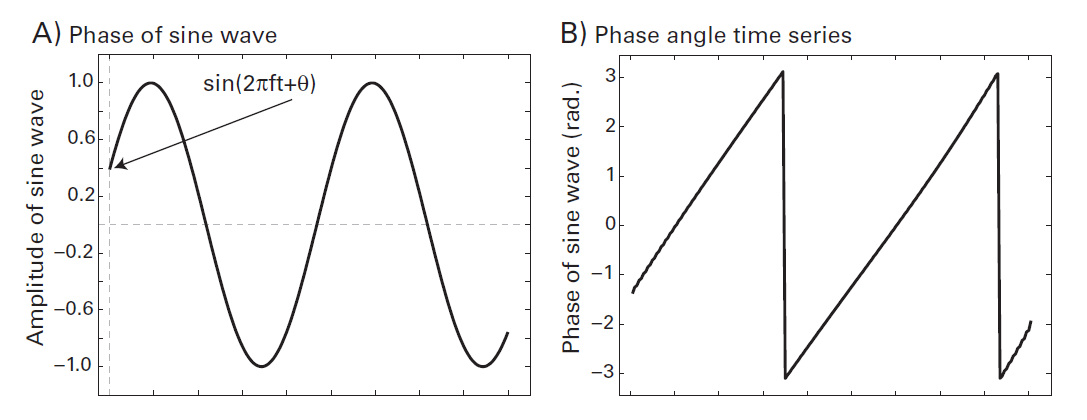

**Figure 15.5**

*The difference between the phase values returned from the short-time FFT method and wavelet convolution or filter-Hilbert.*

These two values have different interpretations but can often be used in the same way in analyses. One example is with intertrial phase clustering, which is a measure of the consistency of band-specific activity over trials.

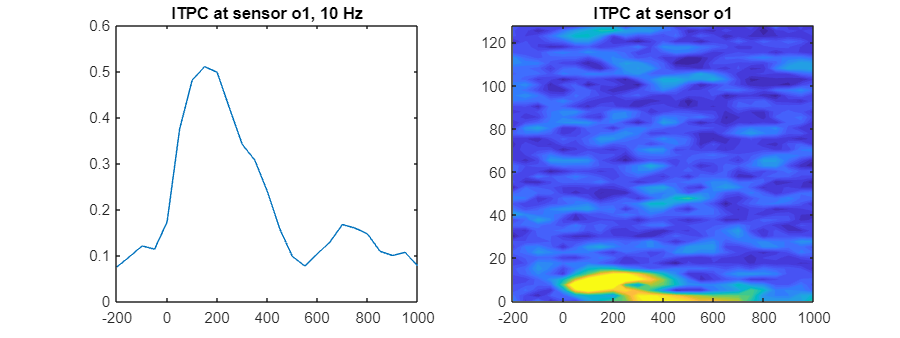

chan2use = 'o1';
frequency2plot = 10;

[~,freq2plotidx]=min(abs(frex-frequency2plot));

itpc = zeros(length(frex),length(times2save));

for timepointi=1:length(times2save)
    
    tempdat = squeeze(EEG.data(strcmpi(chan2use,{EEG.chanlocs.labels}),times2saveidx(timepointi)-floor(timewinidx/2):times2saveidx(timepointi)+floor(timewinidx/2)-mod(timewinidx+1,2),:));
    taperdat = tempdat.*repmat(hann_win',1,EEG.trials);
    fdat = fft(taperdat,[],1)/timewinidx;
    itpc(:,timepointi) = abs(mean(exp(1i*angle(fdat(1:floor(timewinidx/2)+1,:))),2));

end

figure(Position=[100,100,800,300])

subplot(121)
plot(times2save,mean(itpc(freq2plotidx-2:freq2plotidx+2,:),1))
title([ 'ITPC at sensor ' chan2use ', ' num2str(frequency2plot) ' Hz' ])
set(gca,'xlim',[-200 1000])

subplot(122)
contourf(times2save,frex,itpc,40,'linecolor','none')
set(gca,'clim',[0 .5],'xlim',[-200 1000])
title([ 'ITPC at sensor ' chan2use ])

**Figure 15.6**

*Intertrial phase clustering (ITPC), a measure of the consistency of phase values at each time-frequency point over trials, computed using the phase information from the short-time FFT method.*

## 15.5 Describing This Analysis in Your Methods Section

If you use the short-time FFT approach to analyze your data, make sure the Methods section in your paper clearly states the relevant parameters so that someone else could replicate your analyses. The relevant parameters include:

- The overlap between successive time segments

- How many frequencies were extracted (that is, the requested frequencies)

- Whether the time segment length changed as a function of requested frequency

- Whether neighboring frequencies were averaged together

- Which function was used to taper the data

If you used a software package or toolbox such as eeglab, write which functions were used, and any parameters that were changed from their default settings.